# Part I: Histogram and entropy

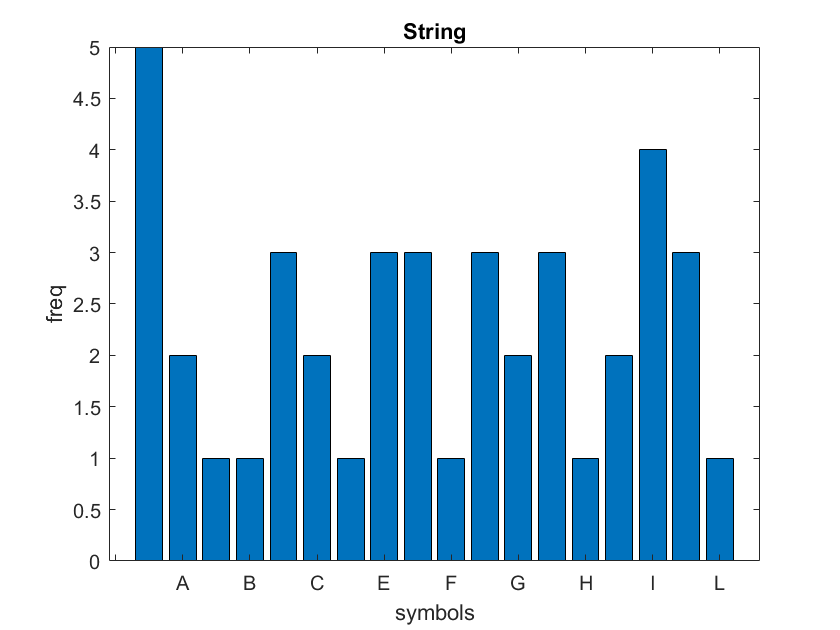

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

clear all; close all; clc;
str = "HUFFMAN IS THE BEST COMPRESSION ALGORITHM";
imrgb = imread('./peppers_rgb.png');
imgray = imread('./peppers_gray.png');
X = str;
if isa(X,'uint8') and size(X,3)==3 % color image input
    %convert RGB to YCbCr and only takes the CbCr
    imycbcr = rgb2ycbcr(X);
    y = imycbcr(:,:,1);
    cb = imycbcr(:,:,2);
    cr = imycbcr(:,:,3);
    [sym_cb, freq_cb,entropy_cb,cr_cb] = myEntropy(cb);
    display('the unique symbols:',str(char(sym)));
    display('The corresponding occurrence probability:',freq/sum(freq));
    display('the entropy of this file (bit per unit):',entropy);
    display('the compression ratio compared to 8bpu:',cr);
%     [sym_cr, freq_cr,entropy_cr,cr_cr] = myEntropy(cr);
%     display('the unique symbols:',char(sym));
%     display('The corresponding occurrence probability:',freq/sum(freq));
%     display('the entropy of this file (bit per unit):',entropy);
%     display('the compression ratio compared to 8bpu:',cr);
else
    [sym, freq,entropy,cr] = myEntropy(X);
    %display('the unique symbols:',string(char(sym)));
    display(sprintf('The corresponding occurrence probability:',num2str(freq/sum(freq))));
    display('the entropy of this file (bit per unit):',entropy);
    display('the compression ratio compared to 8bpu:',cr);
end 


%result of Cb vs Cr...

## Part II : Huffman encoder

clear all; close all; clc;
str = "HUFFMAN IS THE BEST COMPRESSION ALGORITHM";
codebook = HuffmanCompressionAlgorithm(char(str));
sum = 0;
for i=1:numel(codebook(:,2))
    sum = sum + strlength(codebook(i,2));
end
%sprintf('sum is ',num2str(sum));





